First, compare r2 value of fits to growth rates:

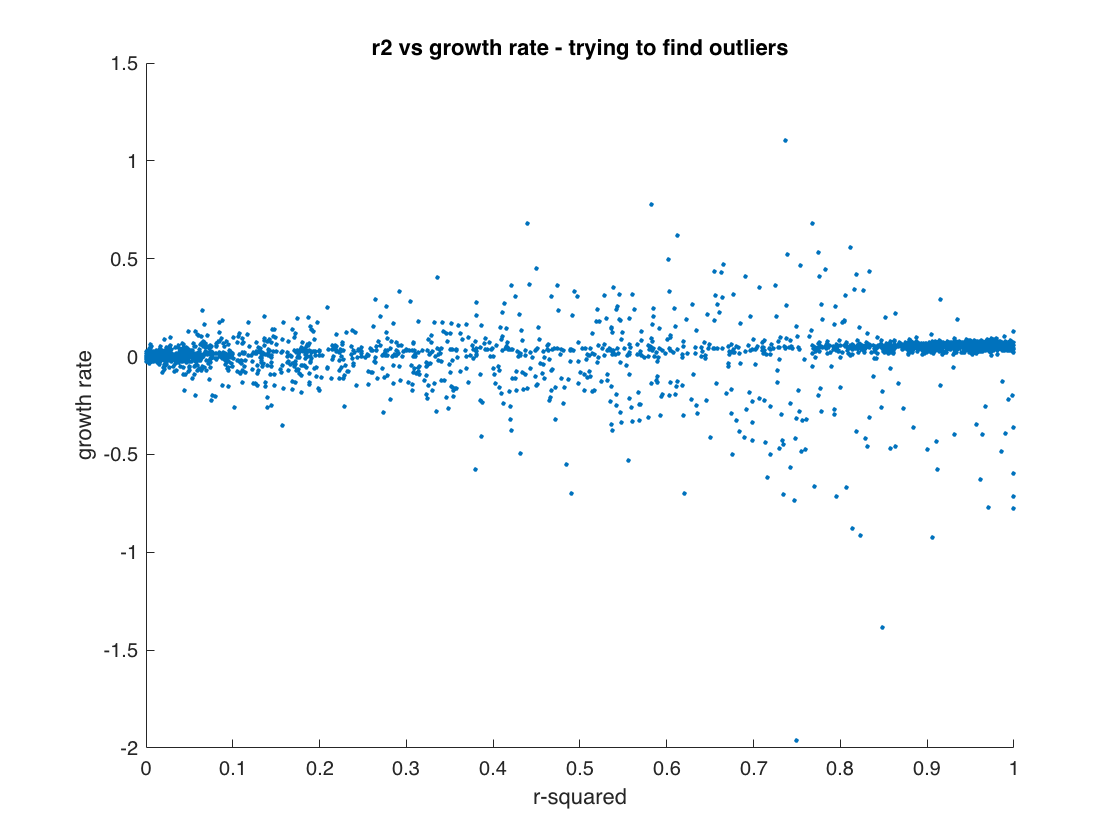

figure
scatter(lt_results.r2,lt_results.growth_rate,5,'filled')
xlabel("r-squared")
ylabel("growth rate")
title("r2 vs growth rate - trying to find outliers")

Most outliers can be removed by limiting r2 to not include perfect fits, most likely due to a limited number of overvations. Since we are excluding the first and last point observed for a lifetime, up to 4 observations will lead to a perfect fit.

These points are most likely miss segmentations. The sampling rate for this experiment is 2 minutes - so 4 observed points for a cell-lifetime will relate to at most a 12 minute division time - which has never been observed in E Coli, even for strains optimized to have a fast division time(cite). In comparision here we are expressing either flouresent or also β-lactamase - our prior assumption is cell dvision times will not be lower than the fastest divison times of the WT strain in ideal conditions.

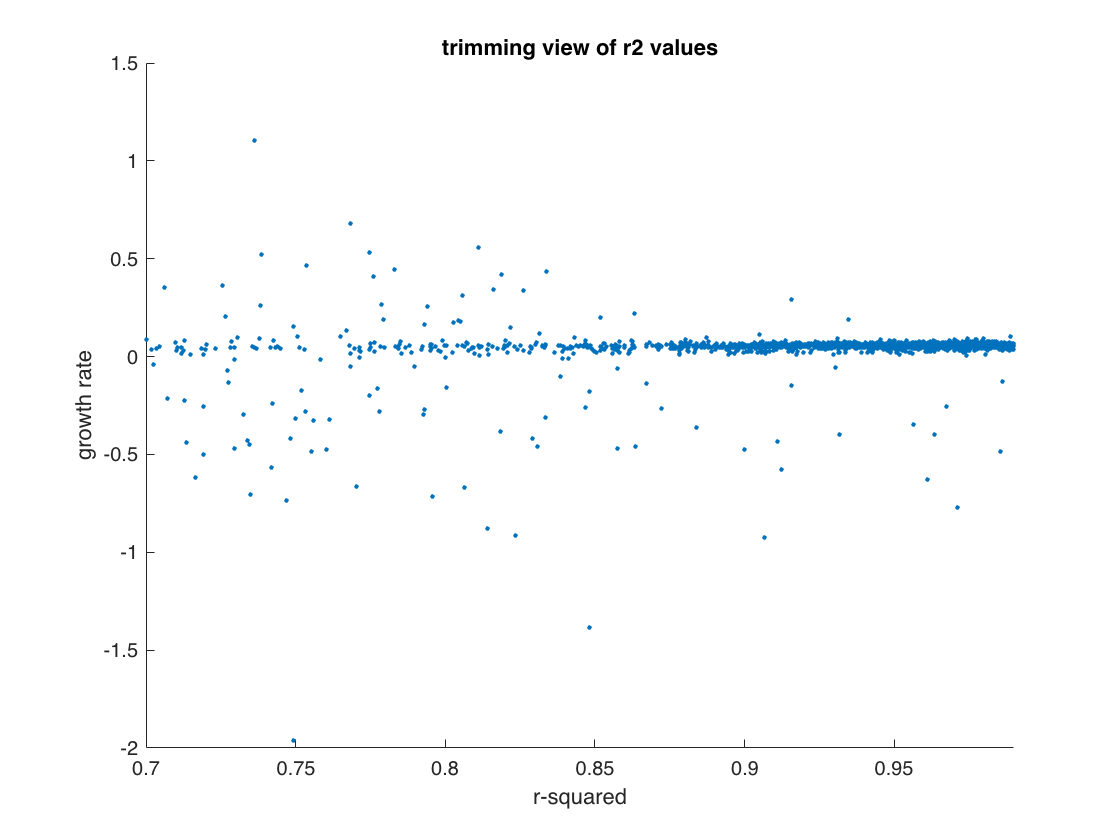

figure
scatter(lt_results.r2,lt_results.growth_rate,5,'filled')
xlim([0.7 0.99])
xlabel("r-squared")
ylabel("growth rate")
title("trimming view of r2 values")

The number of points retained when removing r2 values above 0.99 and less than 0.7 are:


keep =  lt_results.r2<0.99 & lt_results.r2>0.7;
keep_gr = lt_results.growth_rate>0 & lt_results.growth_rate<=0.12;
percent_keeping = sum(keep)/length(keep)

percent_keeping = 0.7552

Looking at the retained values, we can segment the population in two - those expressing YFP and those that are not.

The cells expressing YFP must contain the plasmid ampR:YFP

The cells not expressing YFP either didn't contain the plasmid initially or lost them

By obeserving the histogram of YFP intentsity we can segment these two populations, a value of 250 seems to be a good threshold.

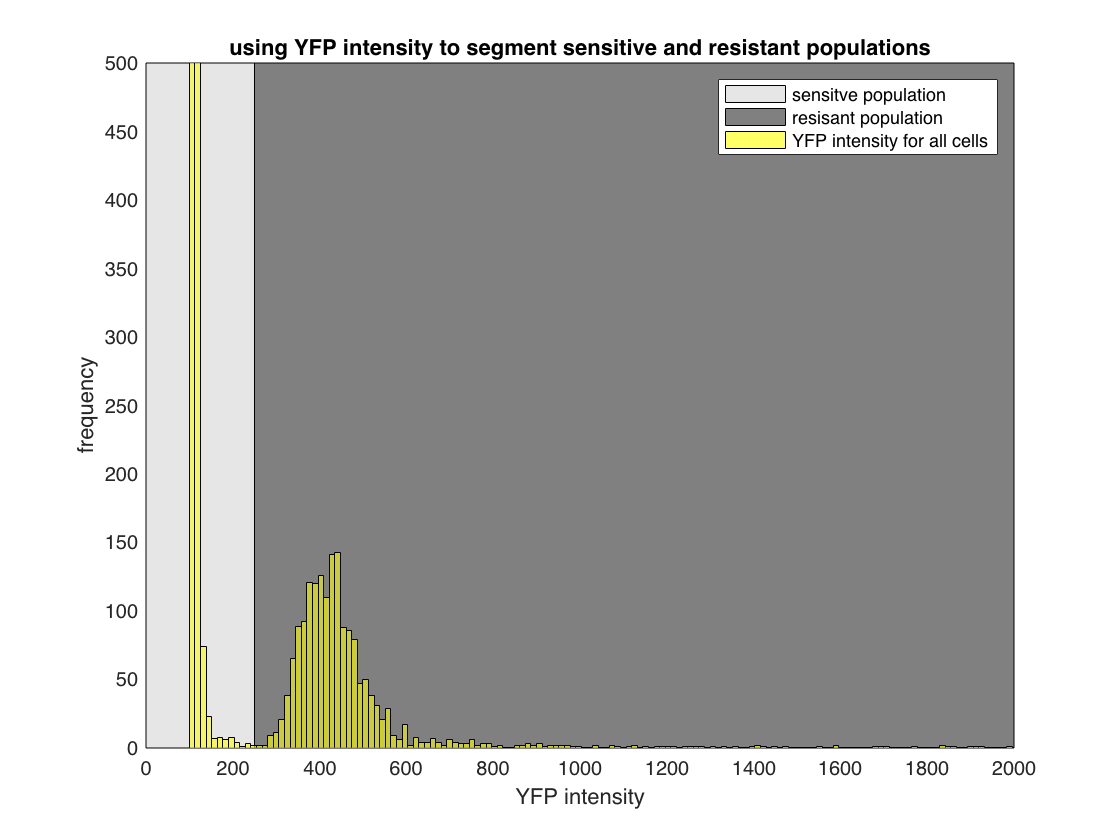

clf
threshold = 250;
hold on
patch([threshold,0,0,threshold],[0,0,500,500],0.9*ones(1,3))
patch([2000,threshold,threshold,2000],[0,0,500,500],0.5*ones(1,3))
histogram(lt_results.yfp_intensity(keep),1000,'FaceColor','yellow')
ylim([0 500])
xlim([0 2000])
xlabel("YFP intensity")
ylabel("frequency")
legend("sensitve population","resisant population","YFP intensity for all cells")
title("using YFP intensity to segment sensitive and resistant populations")

sensitive_id = keep & (lt_results.yfp_intensity<250);
resistant_id = keep & (lt_results.yfp_intensity>=250);
number_sensitive_lifetimes = sum(sensitive_id)

number_sensitive_lifetimes = 4216

number_resistant_lifetimes = sum(resistant_id)

number_resistant_lifetimes = 1758

Note there seems to be a large discreptancy between populations

Looking at the growth rate distributions

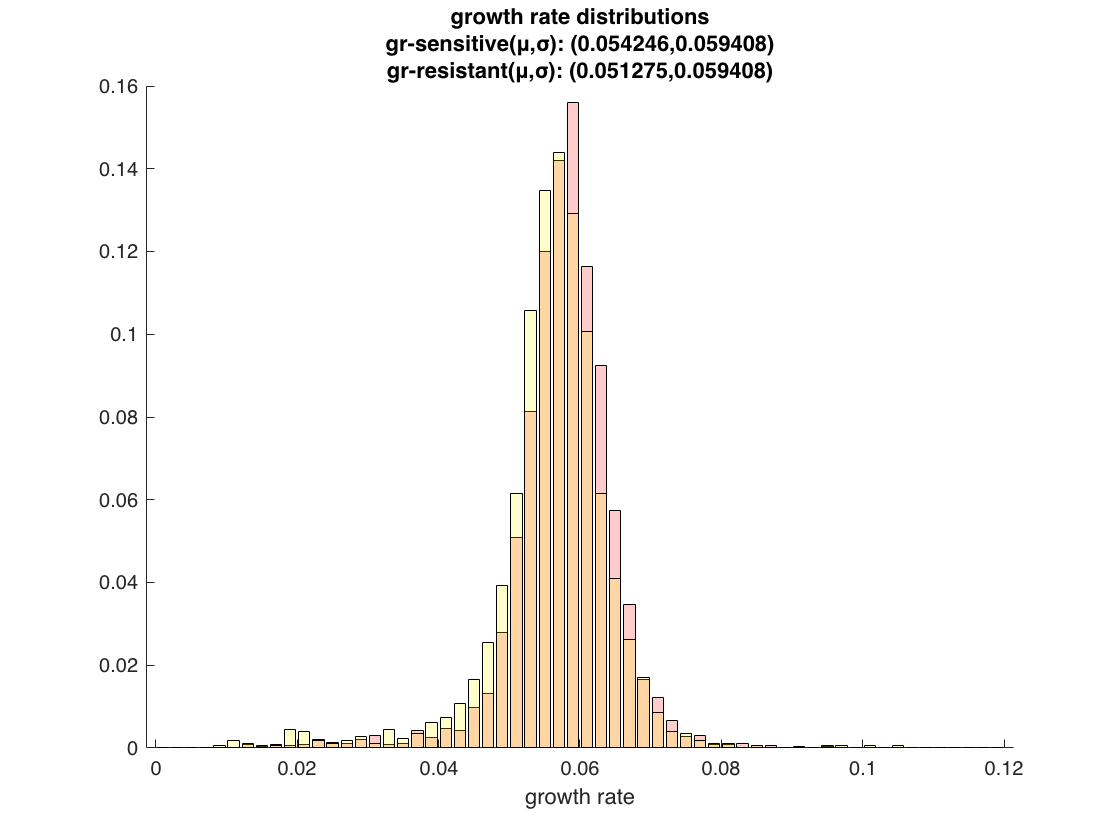

growth_rate_mean_sensitive = mean(lt_results.growth_rate(sensitive_id));
growth_rate_stdd_sensitive = std(lt_results.growth_rate(sensitive_id));
growth_rate_mean_resistant = mean(lt_results.growth_rate(resistant_id));
growth_rate_stdd_resistant = std(lt_results.growth_rate(sensitive_id));
res = 0.002;
E = 0:res:0.12;

[sN,sedges] = histcounts(lt_results.growth_rate(sensitive_id),E,'Normalization','probability');
[rN,redges] = histcounts(lt_results.growth_rate(resistant_id),E,'Normalization','probability');
clf
hold on
bar(E(1:end-1)+res/2,sN,'red','FaceAlpha',0.2)
bar(E(1:end-1)+res/2,rN,'yellow','FaceAlpha',0.2)
hold off
xlabel("growth rate")
title(["growth rate distributions",...
    "gr-sensitive(μ,σ): ("+num2str(growth_rate_mean_sensitive)+","+...
    num2str(growth_rate_stdd_sensitive)+")", ...
    "gr-resistant(μ,σ): ("+num2str(growth_rate_mean_resistant)+","+...
    num2str(growth_rate_stdd_resistant)+")"])

Repeating for the division time distribution

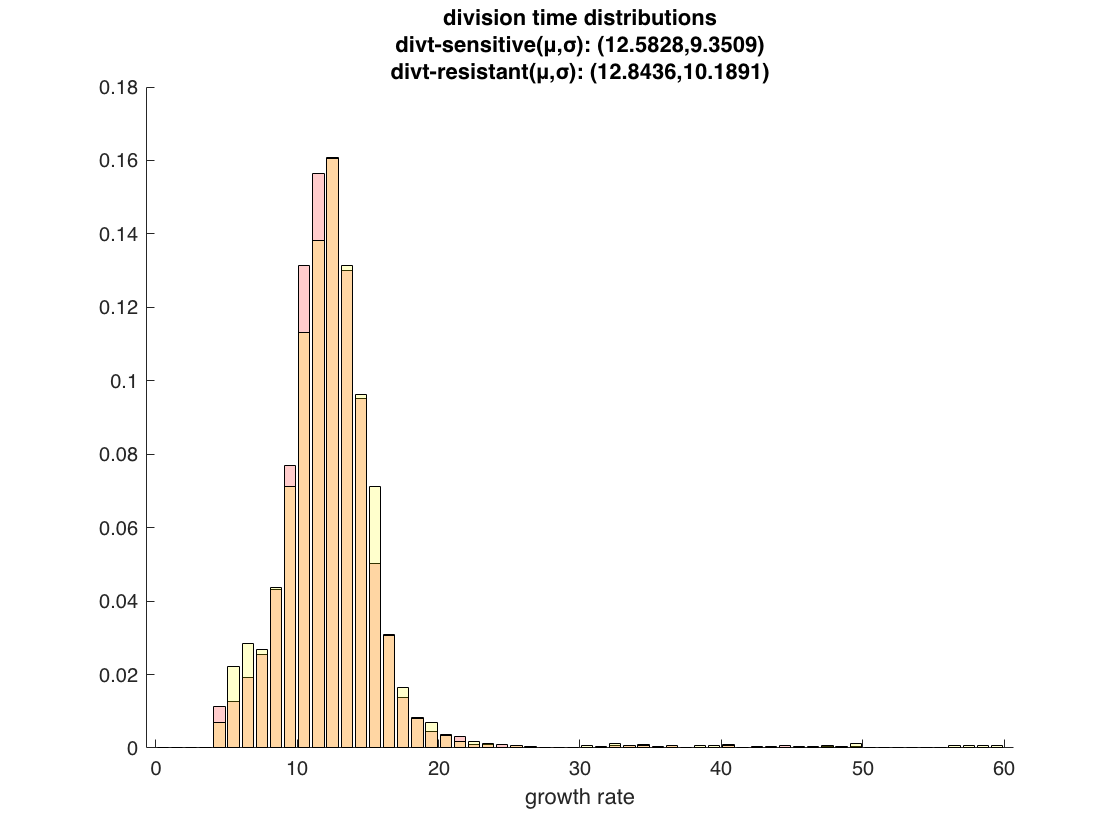

division_time_mean_sensitive = mean(lt_results.division_time(sensitive_id));
division_time_stdd_sensitive = std(lt_results.division_time(sensitive_id));
division_time_mean_resistant = mean(lt_results.division_time(resistant_id));
division_time_stdd_resistant = std(lt_results.division_time(resistant_id));
res = 1;
E = 0:res:60;
[sN,sedges] = histcounts(lt_results.division_time(sensitive_id),E,'Normalization','probability');
[rN,redges] = histcounts(lt_results.division_time(resistant_id),E,'Normalization','probability');
clf
hold on
bar(E(1:end-1)+res/2,sN,'red','FaceAlpha',0.2)
bar(E(1:end-1)+res/2,rN,'yellow','FaceAlpha',0.2)
hold off
xlabel("growth rate")
title(["division time distributions",...
    "divt-sensitive(μ,σ): ("+num2str(division_time_mean_sensitive)+","+...
    num2str(division_time_stdd_sensitive)+")", ...
    "divt-resistant(μ,σ): ("+num2str(division_time_mean_resistant)+","+...
    num2str(division_time_stdd_resistant)+")"])